# EE 354 Homework 8 

# Computer Exercise 7: Digital Processing of EKG (electrocaridograph) Data

## 3A. plot ekg and ekg60n vs time (seconds).

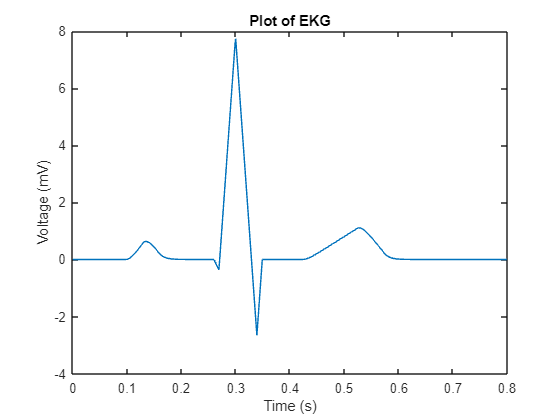

%first, defining the data for the ekg, and ekg60n....
fs = 1000; %sampling frequency
ts = 1/fs; %and time

t = 0:ts:(0.8 - ts); %0.8 is to get a better view of the waveform

%now, setting up vectors to store the data...
ekg = [  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  2.6666667e-003  7.7333333e-003  1.4960000e-002  2.4130667e-002  3.5050933e-002  4.7545840e-002  6.1457923e-002  7.6645464e-002  9.2980917e-002  1.1034949e-001  1.2864788e-001  1.4778309e-001  1.6767145e-001  1.8823764e-001  2.0941387e-001  2.3113915e-001  2.5335857e-001  2.7602271e-001  2.9908711e-001  3.2251173e-001  3.4626056e-001  3.7030117e-001  3.9460438e-001  4.1914395e-001  4.4389622e-001  4.6883993e-001  4.9395594e-001  5.1922701e-001  5.4463764e-001  5.7017388e-001  5.9048982e-001  6.0610751e-001  6.1749676e-001  6.2508041e-001  6.2923904e-001  6.3031514e-001  6.2861696e-001  6.2442193e-001  6.1797973e-001  6.0951509e-001  5.9923025e-001  5.8730723e-001  5.7390984e-001  5.5918552e-001  5.4326697e-001  5.2627360e-001  5.0831291e-001  4.8948162e-001  4.6986679e-001  4.4954678e-001  4.2859210e-001  4.0706622e-001  3.8502627e-001  3.6252364e-001  3.3960461e-001  3.1631082e-001  2.9267973e-001  2.6874509e-001  2.4453725e-001  2.2008353e-001  1.9807517e-001  1.7826766e-001  1.6044089e-001  1.4439680e-001  1.2995712e-001  1.1696141e-001  1.0526527e-001  9.4738742e-002  8.5264867e-002  7.6738381e-002  6.9064543e-002  6.2158088e-002  5.5942280e-002  5.0348052e-002  4.5313246e-002  4.0781922e-002  3.6703730e-002  3.3033357e-002  2.9730021e-002  2.6757019e-002  2.4081317e-002  2.1673185e-002  1.9505867e-002  1.7555280e-002  1.5799752e-002  1.4219777e-002  1.2797799e-002  1.1518019e-002  1.0366217e-002  9.3295956e-003  8.3966360e-003  7.5569724e-003  6.8012752e-003  6.1211477e-003  5.5090329e-003  4.9581296e-003  4.4623167e-003  4.0160850e-003  3.6144765e-003  3.2530288e-003  2.9277260e-003  2.6349534e-003  2.3714580e-003  2.1343122e-003  1.9208810e-003  1.7287929e-003  1.5559136e-003  1.4003222e-003  1.2602900e-003  1.1342610e-003  1.0208349e-003  9.1875143e-004  8.2687629e-004  7.4418866e-004  6.6976979e-004  6.0279281e-004  5.4251353e-004  4.8826218e-004  4.3943596e-004  3.9549236e-004  3.5594313e-004  3.2034881e-004  2.8831393e-004  2.5948254e-004  2.3353429e-004  2.1018086e-004  1.8916277e-004  1.7024649e-004  1.5322185e-004  1.3789966e-004  1.2410969e-004  1.1169873e-004  1.0052885e-004  9.0475967e-005  8.1428371e-005  7.3285533e-005  6.5956980e-005  5.9361282e-005  5.3425154e-005  4.8082639e-005  4.3274375e-005  3.8946937e-005  3.5052243e-005  3.1547019e-005  2.8392317e-005  2.5553086e-005  2.2997777e-005  2.0697999e-005  1.8628199e-005  1.6765379e-005  1.5088841e-005  1.3579957e-005  1.2221962e-005  1.0999765e-005  9.8997889e-006  8.9098100e-006  8.0188290e-006  7.2169461e-006  6.4952515e-006  5.8457263e-006  0.0000000e+000 -4.0000000e-002 -8.0000000e-002 -1.2000000e-001 -1.6000000e-001 -2.0000000e-001 -2.4000000e-001 -2.8000000e-001 -3.2000000e-001 -3.6000000e-001 -1.3333333e-001  1.3333333e-001  4.0000000e-001  6.6666667e-001  9.3333333e-001  1.2000000e+000  1.4666667e+000  1.7333333e+000  2.0000000e+000  2.2666667e+000  2.5333333e+000  2.8000000e+000  3.0666667e+000  3.3333333e+000  3.6000000e+000  3.8666667e+000  4.1333333e+000  4.4000000e+000  4.6666667e+000  4.9333333e+000  5.2000000e+000  5.4666667e+000  5.7333333e+000  6.0000000e+000  6.2666667e+000  6.5333333e+000  6.8000000e+000  7.0666667e+000  7.3333333e+000  7.6000000e+000  7.7333333e+000  7.4666667e+000  7.2000000e+000  6.9333333e+000  6.6666667e+000  6.4000000e+000  6.1333333e+000  5.8666667e+000  5.6000000e+000  5.3333333e+000  5.0666667e+000  4.8000000e+000  4.5333333e+000  4.2666667e+000  4.0000000e+000  3.7333333e+000  3.4666667e+000  3.2000000e+000  2.9333333e+000  2.6666667e+000  2.4000000e+000  2.1333333e+000  1.8666667e+000  1.6000000e+000  1.3333333e+000  1.0666667e+000  8.0000000e-001  5.3333333e-001  2.6666667e-001  0.0000000e+000 -2.6666667e-001 -5.3333333e-001 -8.0000000e-001 -1.0666667e+000 -1.3333333e+000 -1.6000000e+000 -1.8666667e+000 -2.1333333e+000 -2.4000000e+000 -2.6666667e+000 -2.4003333e+000 -2.1336667e+000 -1.8670000e+000 -1.6003333e+000 -1.3336667e+000 -1.0670000e+000 -8.0033333e-001 -5.3366667e-001 -2.6700000e-001 -3.3333333e-004  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  0.0000000e+000  1.3974360e-010  1.2576924e-010  1.1319232e-010  1.0187309e-010  9.1685777e-011  8.2517200e-011  7.4265480e-011  6.6838932e-011  6.0155039e-011  5.4139535e-011  4.8725581e-011  4.3853023e-011  3.9467721e-011  3.5520949e-011  3.1968854e-011  2.8771968e-011  2.5894772e-011  2.3305294e-011  2.0974765e-011  1.8877288e-011  1.6989560e-011  1.5290604e-011  1.3761543e-011  1.2385389e-011  1.1146850e-011  1.0032165e-011  9.0289486e-012  8.1260537e-012  7.3134483e-012  6.5821035e-012  5.9238932e-012  5.3315038e-012  4.7983535e-012  4.3185181e-012  3.8866663e-012  3.4979997e-012  3.1481997e-012  2.8333797e-012  2.5500418e-012  2.2950376e-012  2.0655338e-012  1.8589804e-012  1.6730824e-012  1.5057742e-012  1.3551967e-012  1.2196771e-012  1.0977094e-012  9.8793843e-013  8.8914458e-013  8.0023012e-013  7.2020711e-013  6.4818640e-013  5.8336776e-013  5.2503098e-013  4.7252789e-013  4.2527510e-013  3.8274759e-013  3.4447283e-013  3.1002555e-013  2.7902299e-013  2.5112069e-013  2.2600862e-013  2.0340776e-013  1.8306698e-013  1.6476029e-013  1.2000000e-003  3.4800000e-003  6.7320000e-003  1.0858800e-002  1.5772920e-002  2.1395628e-002  2.7656065e-002  3.4490459e-002  4.1841413e-002  4.9657272e-002  5.7891544e-002  6.6502390e-002  7.5452151e-002  8.4706936e-002  9.4236242e-002  1.0401262e-001  1.1401136e-001  1.2421022e-001  1.3458920e-001  1.4513028e-001  1.5581725e-001  1.6663553e-001  1.7757197e-001  1.8861478e-001  1.9975330e-001  2.1097797e-001  2.2228017e-001  2.3365215e-001  2.4508694e-001  2.5657825e-001  2.6812042e-001  2.7970838e-001  2.9133754e-001  3.0300379e-001  3.1470341e-001  3.2643307e-001  3.3818976e-001  3.4997078e-001  3.6177371e-001  3.7359634e-001  3.8543670e-001  3.9729303e-001  4.0916373e-001  4.2104736e-001  4.3294262e-001  4.4484836e-001  4.5676352e-001  4.6868717e-001  4.8061845e-001  4.9255661e-001  5.0450095e-001  5.1645085e-001  5.2840577e-001  5.4036519e-001  5.5232867e-001  5.6429580e-001  5.7626622e-001  5.8823960e-001  6.0021564e-001  6.1219408e-001  6.2417467e-001  6.3615720e-001  6.4814148e-001  6.6012733e-001  6.7211460e-001  6.8410314e-001  6.9609283e-001  7.0808354e-001  7.2007519e-001  7.3206767e-001  7.4406090e-001  7.5605481e-001  7.6804933e-001  7.8004440e-001  7.9203996e-001  8.0403596e-001  8.1603237e-001  8.2802913e-001  8.4002622e-001  8.5202360e-001  8.6402124e-001  8.7601911e-001  8.8801720e-001  9.0001548e-001  9.1201393e-001  9.2401254e-001  9.3601129e-001  9.4801016e-001  9.6000914e-001  9.7200823e-001  9.8400740e-001  9.9600666e-001  1.0080060e+000  1.0200054e+000  1.0320049e+000  1.0440044e+000  1.0560039e+000  1.0680035e+000  1.0800032e+000  1.0920029e+000  1.1004026e+000  1.1055623e+000  1.1078061e+000  1.1074255e+000  1.1046829e+000  1.0998146e+000  1.0930332e+000  1.0845299e+000  1.0744769e+000  1.0630292e+000  1.0503263e+000  1.0364936e+000  1.0216443e+000  1.0058798e+000  9.8929186e-001  9.7196268e-001  9.5396641e-001  9.3536977e-001  9.1623279e-001  8.9660951e-001  8.7654856e-001  8.5609371e-001  8.3528433e-001  8.1415590e-001  7.9274031e-001  7.7106628e-001  7.4915965e-001  7.2704369e-001  7.0473932e-001  6.8226539e-001  6.5963885e-001  6.3687496e-001  6.1398747e-001  5.9098872e-001  5.6788985e-001  5.4470086e-001  5.2143078e-001  4.9808770e-001  4.7467893e-001  4.5121104e-001  4.2768993e-001  4.0412094e-001  3.8050885e-001  3.5685796e-001  3.3317216e-001  3.0945495e-001  2.8570945e-001  2.6193851e-001  2.3814466e-001  2.1433019e-001  1.9289717e-001  1.7360746e-001  1.5624671e-001  1.4062204e-001  1.2655983e-001  1.1390385e-001  1.0251347e-001  9.2262120e-002  8.3035908e-002  7.4732317e-002  6.7259085e-002  6.0533177e-002  5.4479859e-002  4.9031873e-002  4.4128686e-002  3.9715817e-002  3.5744235e-002  3.2169812e-002  2.8952831e-002  2.6057548e-002  2.3451793e-002  2.1106614e-002  1.8995952e-002  1.7096357e-002  1.5386721e-002  1.3848049e-002  1.2463244e-002  1.1216920e-002  1.0095228e-002  9.0857051e-003  8.1771346e-003  7.3594211e-003  6.6234790e-003  5.9611311e-003  5.3650180e-003  4.8285162e-003  4.3456646e-003  3.9110981e-003  3.5199883e-003  3.1679895e-003  2.8511905e-003  2.5660715e-003  2.3094643e-003  2.0785179e-003  1.8706661e-003  1.6835995e-003  1.5152395e-003  1.3637156e-003  1.2273440e-003  1.1046096e-003  9.9414866e-004  8.9473380e-004  8.0526042e-004  7.2473438e-004  6.5226094e-004  5.8703485e-004  5.2833136e-004  4.7549822e-004  4.2794840e-004  3.8515356e-004  3.4663821e-004  3.1197439e-004  2.8077695e-004  2.5269925e-004  2.2742933e-004  2.0468639e-004  1.8421775e-004  1.6579598e-004  1.4921638e-004  1.3429474e-004  1.2086527e-004  1.0877874e-004  9.7900868e-005  8.8110781e-005  7.9299703e-005  7.1369733e-005  6.4232759e-005  5.7809483e-005  5.2028535e-005  4.6825682e-005  4.2143113e-005  3.7928802e-005  3.4135922e-005  3.0722330e-005  2.7650097e-005  2.4885087e-005  2.2396578e-005  2.0156920e-005  1.8141228e-005  1.6327106e-005  1.4694395e-005  1.3224956e-005  1.1902460e-005  1.0712214e-005  9.6409926e-006  8.6768933e-006  7.8092040e-006  7.0282836e-006  6.3254552e-006  5.6929097e-006  5.1236187e-006  4.6112569e-006  4.1501312e-006  3.7351181e-006  3.3616063e-006  3.0254456e-006  2.7229011e-006  2.4506110e-006  2.2055499e-006  1.9849949e-006  1.7864954e-006  1.6078459e-006  1.4470613e-006  1.3023551e-006  1.1721196e-006  1.0549077e-006  9.4941690e-007  8.5447521e-007  7.6902769e-007  6.9212492e-007  6.2291243e-007  5.6062118e-007  5.0455907e-007  4.5410316e-007  4.0869284e-007  3.6782356e-007  3.3104120e-007  2.9793708e-007  2.6814337e-007  2.4132904e-007  2.1719613e-007  1.9547652e-007  1.7592887e-007  1.5833598e-007  1.4250238e-007  1.2825214e-007  1.1542693e-007  1.0388424e-007  9.3495813e-008  8.4146232e-008  7.5731609e-008  6.8158448e-008  6.1342603e-008  5.5208343e-008  4.9687509e-008  4.4718758e-008  4.0246882e-008  3.6222194e-008  3.2599974e-008  2.9339977e-008  2.6405979e-008  2.3765381e-008  2.1388843e-008  1.9249959e-008  1.7324963e-008  1.5592467e-008  1.4033220e-008  1.2629898e-008  1.1366908e-008  1.0230217e-008  9.2071957e-009  8.2864761e-009  7.4578285e-009  6.7120456e-009  6.0408411e-009  5.4367570e-009  4.8930813e-009  4.4037731e-009  3.9633958e-009  3.5670562e-009  3.2103506e-009  2.8893156e-009  2.6003840e-009  2.3403456e-009  2.1063110e-009  1.8956799e-009  1.7061119e-009  1.5355007e-009  1.3819507e-009  1.2437556e-009  1.1193800e-009  1.0074420e-009  9.0669784e-010  8.1602805e-010  7.3442525e-010  6.6098272e-010  5.9488445e-010  5.3539601e-010  4.8185641e-010  4.3367076e-010  3.9030369e-010  3.5127332e-010  3.1614599e-010  2.8453139e-010  2.5607825e-010  2.3047042e-010  2.0742338e-010  1.8668104e-010  1.6801294e-010  1.5121165e-010  1.3609048e-010  1.2248143e-010  1.1023329e-010  9.9209961e-011  8.9288965e-011  8.0360068e-011  7.2324061e-011  6.5091655e-011  5.8582490e-011  5.2724241e-011  4.7451817e-011  4.2706635e-011  3.8435972e-011  3.4592374e-011  3.1133137e-011  2.8019823e-011  2.5217841e-011  2.2696057e-011  2.0426451e-011  1.8383806e-011  1.6545425e-011  1.4890883e-011  1.3401795e-011  1.2061615e-011  1.0855454e-011];
ekg60n = [  7.3626562e-001  1.3691201e+000  1.8096768e+000  1.9960579e+000  1.9020856e+000  1.5409585e+000  9.6339838e-001  2.5052548e-001 -4.9753462e-001 -1.1757142e+000 -1.6887605e+000 -1.9646144e+000 -1.9645312e+000 -1.6885226e+000 -1.1753549e+000 -4.9710449e-001  2.5096606e-001  9.6378752e-001  1.5412416e+000  1.9022228e+000  1.9960300e+000  1.8094877e+000  1.3687964e+000  7.3585271e-001 -4.4407846e-004 -7.3667850e-001 -1.3694438e+000 -1.8098658e+000 -1.9960857e+000 -1.9019483e+000 -1.5406754e+000 -9.6300920e-001 -2.5008490e-001  4.9796472e-001  1.1760734e+000  1.6889984e+000  1.9646975e+000  1.9644479e+000  1.6882845e+000  1.1749956e+000  4.9667433e-001 -2.5140662e-001 -9.6417661e-001 -1.5415246e+000 -1.9023599e+000 -1.9960020e+000 -1.8092985e+000 -1.3684725e+000 -7.3543976e-001  8.8815689e-004  7.3709133e-001  1.3697674e+000  1.8100548e+000  1.9961135e+000  1.9018109e+000  1.5403922e+000  9.6261997e-001  2.4964430e-001 -4.9839481e-001 -1.1764326e+000 -1.6892362e+000 -1.9647806e+000 -1.9643645e+000 -1.6880464e+000 -1.1746362e+000 -4.9624415e-001  2.5184717e-001  9.6456566e-001  1.5418075e+000  1.9024969e+000  1.9959739e+000  1.8091092e+000  1.3681487e+000  7.3502678e-001 -1.3322353e-003 -7.3750413e-001 -1.3700909e+000 -1.8102436e+000 -1.9961411e+000 -1.9016734e+000 -1.5401090e+000 -9.6223068e-001 -2.4920368e-001  4.9882486e-001  1.1767917e+000  1.6894739e+000  1.9648635e+000  1.9642810e+000  1.6878082e+000  1.1742768e+000  4.9581395e-001 -2.5228771e-001 -9.6495465e-001 -1.5420903e+000 -1.9026338e+000 -1.9959457e+000 -1.8089198e+000 -1.3678247e+000 -7.3461376e-001  1.7763136e-003  7.4058357e-001  1.3781478e+000  1.8253924e+000  2.0202993e+000  1.9365868e+000  1.5873714e+000  1.0232993e+000  3.2540852e-001 -4.0627398e-001 -1.0668012e+000 -1.5610636e+000 -1.8171632e+000 -1.7965259e+000 -1.4993323e+000 -9.6450339e-001 -2.6424457e-001  5.0608680e-001  1.2413663e+000  1.8414601e+000  2.2252824e+000  2.3421779e+000  2.1790315e+000  1.7621051e+000  1.1533447e+000  4.4167583e-001 -2.6948970e-001 -8.7678190e-001 -1.2913940e+000 -1.4515584e+000 -1.3312243e+000 -9.4905235e-001 -3.5534447e-001  3.6917433e-001  1.1247653e+000  1.8067487e+000  2.3202642e+000  2.5936460e+000  2.5885356e+000  2.3053113e+000  1.7830728e+000  1.0941837e+000  3.3413848e-001 -3.9182267e-001 -9.8347017e-001 -1.3596404e+000 -1.4696153e+000 -1.3002279e+000 -8.7769499e-001 -2.6392082e-001  4.5221125e-001  1.1673344e+000  1.7781274e+000  2.1958359e+000  2.3587470e+000  2.2408650e+000  1.8555695e+000  1.2537423e+000  5.1662687e-001 -2.5557763e-001 -9.5778510e-001 -1.4921113e+000 -1.7868440e+000 -1.8035890e+000 -1.5426963e+000 -1.0432410e+000 -3.7756178e-001  3.5887451e-001  1.0608601e+000  1.6282031e+000  1.9797824e+000  2.0649250e+000  1.8705092e+000  1.4227947e+000  7.8372254e-001  4.2204698e-002 -6.9837305e-001 -1.3346807e+000 -1.7779647e+000 -1.9665206e+000 -1.8743655e+000 -1.5148938e+000 -9.3899990e-001 -2.2793525e-001  5.1810012e-001  1.1940272e+000  1.7046437e+000  1.9779920e+000  1.9754640e+000  1.6972208e+000  1.1821680e+000  5.0248953e-001 -2.4649276e-001 -9.5970889e-001 -1.5370996e+000 -1.8976715e+000 -1.9908737e+000 -1.8036991e+000 -1.3625122e+000 -7.2934685e-001  6.8056547e-003  7.4249532e-001  1.3743426e+000  1.8135579e+000  1.9984120e+000  1.9029055e+000  1.5404202e+000  9.6183948e-001  2.4840077e-001 -4.9971449e-001 -1.1774520e+000 -1.6896403e+000 -1.9643579e+000 -1.9630351e+000 -1.6858718e+000 -1.1718089e+000 -4.9305977e-001  2.5503272e-001  9.6738718e-001  1.5439427e+000  1.9037125e+000  1.9961591e+000  1.8082919e+000  1.3664923e+000  7.3280761e-001 -3.7631692e-003 -7.3977000e-001 -1.3718416e+000 -1.8112046e+000 -1.9961515e+000 -1.9007087e+000 -1.5382836e+000 -9.5978230e-001 -2.4645923e-001  5.0149516e-001  1.1790265e+000  1.6909717e+000  1.9654250e+000  1.9638373e+000  1.6864307e+000  1.1721670e+000  4.9327549e-001 -2.5489172e-001 -9.6725258e-001 -1.5437540e+000 -1.9034250e+000 -1.9957488e+000 -1.8077586e+000 -1.3658589e+000 -7.3211626e-001  4.4575463e-003  7.4040781e-001  1.3723675e+000  1.8115752e+000  1.9963427e+000  1.9007183e+000  1.5381328e+000  9.5951241e-001  2.4612628e-001 -5.0182807e-001 -1.1792979e+000 -1.6911355e+000 -2.0054412e+000 -2.0436938e+000 -1.8061385e+000 -1.3317590e+000 -6.9280184e-001  1.5371118e-002  6.8767629e-001  1.2240679e+000  1.5435896e+000  1.8624121e+000  1.9409250e+000  1.7655552e+000  1.3983883e+000  9.2844848e-001  4.5919476e-001  9.3989792e-002 -7.8417816e-002  3.6414871e-003  3.6609647e-001  9.9549331e-001  1.8408853e+000  2.8209883e+000  3.8355978e+000  4.7796624e+000  5.5580392e+000  6.0988567e+000  6.3636095e+000  6.3525663e+000  6.1047324e+000  5.6923714e+000  5.2108551e+000  4.7652684e+000  4.4556499e+000  4.3629409e+000  4.5376169e+000  4.9925985e+000  5.7014360e+000  6.6020250e+000  7.6053289e+000  8.4745510e+000  8.8396665e+000  9.0119392e+000  8.9297186e+000  8.5670985e+000  7.9375561e+000  7.0920584e+000  6.1119043e+000  5.0973057e+000  4.1533124e+000  3.3750572e+000  2.8343946e+000  2.5698082e+000  2.5810060e+000  2.8289609e+000  3.2413923e+000  3.7229186e+000  4.1684535e+000  4.4779656e+000  4.5705285e+000  4.3956873e+000  3.9405447e+000  3.2315728e+000  2.3308950e+000  1.3275603e+000  3.2503652e-001 -5.7332268e-001 -1.2787938e+000 -1.7297452e+000 -1.9002935e+000 -1.8039387e+000 -1.4916686e+000 -1.0447969e+000 -5.6354259e-001 -1.5295386e-001  9.1846364e-002  9.9020731e-002 -1.6989271e-001 -7.1457839e-001 -1.4959875e+000 -1.9088228e+000 -2.3903591e+000 -2.8358420e+000 -3.1452476e+000 -3.2376645e+000 -3.0626581e+000 -2.6073544e+000 -1.8982482e+000 -9.9748158e-001  5.8837551e-003  7.4204255e-001  1.3736455e+000  1.8123150e+000  1.9964384e+000  1.9001549e+000  1.5369879e+000  9.5794547e-001  2.4435615e-001 -5.0355386e-001 -1.1807379e+000 -1.6920832e+000 -1.9657693e+000 -1.9633561e+000 -1.6851825e+000 -1.1703190e+000 -4.9108010e-001  2.5713279e-001  9.6923046e-001  1.5451963e+000  1.9041337e+000  1.9956288e+000  1.8068307e+000  1.3642568e+000  7.3006817e-001 -6.6611646e-003 -7.4245491e-001 -1.3739682e+000 -1.8125028e+000 -1.9964649e+000 -1.9000163e+000 -1.5367037e+000 -9.5755562e-001 -2.4391539e-001  5.0398362e-001  1.1810963e+000  1.6923199e+000  1.9658510e+000  1.9632714e+000  1.6849433e+000  1.1699589e+000  4.9064960e-001 -2.5757318e-001 -9.6961889e-001 -1.5454782e+000 -1.9042695e+000 -1.9955994e+000 -1.8066403e+000 -1.3639321e+000 -7.2965471e-001  7.1052404e-003  7.4286724e-001  1.3742909e+000  1.8126905e+000  1.9964912e+000  1.8998776e+000  1.5364195e+000  9.5716572e-001  2.4347462e-001 -5.0441335e-001 -1.1814547e+000 -1.6925565e+000 -1.9659327e+000 -1.9631866e+000 -1.6847040e+000 -1.1695987e+000 -4.9021908e-001  2.5801355e-001  9.7000726e-001  1.5457600e+000  1.9044052e+000  1.9955699e+000  1.8064497e+000  1.3636072e+000  7.2924122e-001 -7.5493159e-003 -7.4207953e-001 -1.3711335e+000 -1.8061461e+000 -1.9856587e+000 -1.8839659e+000 -1.5147395e+000 -9.2911971e-001 -2.0854338e-001  5.4668448e-001  1.2314702e+000  1.7506846e+000  2.0325166e+000  2.0385539e+000  1.7691716e+000  1.2634747e+000  5.9380116e-001 -1.4444256e-001 -8.4618537e-001 -1.4114525e+000 -1.7594105e+000 -1.8397231e+000 -1.6396236e+000 -1.1857104e+000 -5.4021292e-001  2.0774669e-001  9.5466975e-001  1.5972162e+000  2.0467177e+000  2.2416305e+000  2.1561782e+000  1.8039712e+000  1.2360942e+000  5.3393059e-001 -2.0226896e-001 -8.6746778e-001 -1.3665964e+000 -1.6279060e+000 -1.6130460e+000 -1.3224515e+000 -7.9528180e-001 -1.0392127e-001  6.5618729e-001  1.3799476e+000  1.9673708e+000  2.3376190e+000  2.4403590e+000  2.2628319e+000  1.8316446e+000  1.2090326e+000  4.8411914e-001 -2.3960305e-001 -8.5880762e-001 -1.2848472e+000 -1.4562045e+000 -1.3471323e+000 -9.7127044e-001 -3.7972953e-001  3.4608736e-001  1.1059181e+000  1.7947234e+000  2.3174405e+000  2.6023343e+000  2.6110732e+000  2.3441130e+000  1.8406324e+000  1.1730305e+000  4.3675823e-001 -2.6308856e-001 -8.2652984e-001 -1.1727441e+000 -1.2514200e+000 -1.0498228e+000 -5.9458302e-001  5.2043855e-002  8.0092150e-001  1.5485521e+000  2.1916132e+000  2.6414694e+000  2.8366218e+000  2.7513455e+000  2.3993029e+000  1.8316248e+000  1.1297286e+000  3.9388343e-001 -2.7087353e-001 -7.6948958e-001 -1.0302471e+000 -1.0148364e+000 -7.2373690e-001 -1.9614911e-001  4.9551064e-001  1.2557816e+000  1.9795663e+000  2.5668919e+000  2.9369519e+000  3.0394554e+000  2.8616906e+000  2.4303108e+000  1.8075901e+000  1.0826773e+000  3.5547426e-001 -2.7034087e-001 -7.0582146e-001 -8.8919597e-001 -7.9449981e-001 -4.3518240e-001  1.3781764e-001  8.4325926e-001  1.5810385e+000  2.2462747e+000  2.7440646e+000  3.0028332e+000  2.9844056e+000  2.6893862e+000  2.1570887e+000  1.4600288e+000  6.9375118e-001 -3.6578657e-002 -6.3093520e-001 -1.0084728e+000 -1.1188724e+000 -9.4940200e-001 -5.2669776e-001  8.6982658e-002  8.0251000e-001  1.5164067e+000  2.1253851e+000  2.5408584e+000  2.7013865e+000  2.5813089e+000  2.1943512e+000  1.5917003e+000  8.5481722e-001  8.3997477e-002 -6.1571366e-001 -1.1492736e+000 -1.4449898e+000 -1.4645883e+000 -1.2085876e+000 -7.1622527e-001 -5.9945525e-002  6.6477647e-001  1.3528454e+000  1.9043073e+000  2.2383896e+000  2.3048459e+000  2.0910141e+000  1.6235954e+000  9.6490420e-001  2.0411643e-001 -5.5285533e-001 -1.2029402e+000 -1.6577550e+000 -1.8560508e+000 -1.7723443e+000 -1.4205237e+000 -8.5192166e-001 -1.4812678e-001  5.9045671e-001  1.2586938e+000  1.7614696e+000  2.0270348e+000  2.0170704e+000  1.7320586e+000  1.2112044e+000  5.2692059e-001 -2.2535158e-001 -9.4055474e-001 -1.5187778e+000 -1.8792949e+000 -1.9719089e+000 -1.7840069e+000 -1.3423356e+000 -7.0924944e-001  2.6044554e-002  7.6001258e-001  1.3893330e+000  1.8254056e+000  2.0067936e+000  1.9078504e+000  1.5423198e+000  9.6140428e-001  2.4657152e-001 -5.0188921e-001 -1.1789543e+000 -1.6896179e+000 -1.9622368e+000 -1.9585939e+000 -1.6792668e+000 -1.1635471e+000 -4.8392287e-001  2.6410216e-001  9.7542201e-001  1.5500904e+000  1.9073581e+000  1.9970141e+000  1.8064375e+000  1.3623699e+000  7.2715937e-001 -9.9972949e-003 -7.4558238e-001 -1.3762971e+000 -1.8135703e+000 -1.9959991e+000 -1.8979729e+000 -1.5332707e+000 -9.5312620e-001 -2.3903166e-001  5.0870780e-001  1.1850623e+000  1.6950289e+000  1.9669753e+000  1.9627002e+000  1.6827994e+000  1.1665818e+000  4.8654801e-001 -2.6179212e-001 -9.7333470e-001 -1.5481438e+000 -1.9054880e+000 -1.9951792e+000 -1.8046221e+000 -1.3605829e+000 -7.2543010e-001  1.1625276e-002  7.4705986e-001  1.3775780e+000  1.8146202e+000  1.9968013e+000  1.8985323e+000  1.5336149e+000  9.5330210e-001  2.3910041e-001 -5.0867861e-001 -1.1850073e+000 -1.6948932e+000 -1.9667216e+000 -1.9623135e+000 -1.6822885e+000 -1.1659772e+000 -4.8589786e-001  2.6242981e-001  9.7390029e-001  1.5485848e+000  1.9057667e+000  1.9952783e+000  1.8045473e+000  1.3603623e+000  7.2511069e-001 -1.1984354e-002 -7.4739529e-001 -1.3778311e+000 -1.8147449e+000 -1.9967707e+000 -1.8983424e+000 -1.5332846e+000 -9.5287103e-001 -2.3862292e-001  5.0914100e-001  1.1853946e+000  1.6951556e+000  1.9668262e+000  1.9622493e+000  1.6820677e+000  1.1656339e+000  4.8548283e-001 -2.6285587e-001 -9.7427538e-001 -1.5488543e+000 -1.9058910e+000 -1.9952384e+000 -1.8043474e+000 -1.3600292e+000 -7.2469003e-001  1.2434526e-002  7.4781267e-001  1.3781579e+000  1.8149360e+000  1.9967999e+000  1.8982062e+000  1.5330027e+000  9.5248349e-001  2.3818464e-001 -5.0956807e-001 -1.1857501e+000 -1.6953893e+000 -1.9669050e+000 -1.9621618e+000 -1.6818260e+000 -1.1652717e+000 -4.8505089e-001  2.6329711e-001  9.7466410e-001  1.5491361e+000  1.9060263e+000  1.9952084e+000  1.8041564e+000  1.3597041e+000  7.2427660e-001 -1.2878157e-002 -7.4822412e-001 -1.3784793e+000 -1.8151222e+000 -1.9968247e+000 -1.8980660e+000 -1.5327172e+000 -9.5209277e-001 -2.3774352e-001  5.0999765e-001  1.1861078e+000  1.6956250e+000  1.9669855e+000  1.9620759e+000  1.6815858e+000  1.1649109e+000  4.8462014e-001 -2.6373724e-001 -9.7505179e-001 -1.5494168e+000 -1.9061607e+000 -1.9951776e+000 -1.8039646e+000 -1.3593784e+000 -7.2386261e-001  1.3322257e-002  7.4863596e-001  1.3788011e+000  1.8153087e+000  1.9968497e+000  1.8979260e+000  1.5324319e+000  9.5170223e-001  2.3730260e-001 -5.1042703e-001 -1.1864654e+000 -1.6958604e+000 -1.9670658e+000 -1.9619898e+000 -1.6813453e+000 -1.1645499e+000 -4.8418928e-001  2.6417744e-001  9.7543950e-001  1.5496976e+000  1.9062951e+000  1.9951467e+000  1.8037728e+000  1.3590526e+000  7.2344862e-001 -1.3766323e-002 -7.4904774e-001 -1.3791227e+000 -1.8154950e+000 -1.9968745e+000 -1.8977859e+000 -1.5321465e+000 -9.5131163e-001 -2.3686165e-001  5.1085639e-001  1.1868228e+000  1.6960958e+000  1.9671460e+000  1.9619036e+000  1.6811048e+000  1.1641888e+000  4.8375840e-001 -2.6461762e-001 -9.7582715e-001 -1.5499783e+000 -1.9064294e+000 -1.9951158e+000 -1.8035810e+000 -1.3587268e+000 -7.2303459e-001  1.4210391e-002];

%now, plotting the data given...
plot (t, ekg);
    title("Plot of EKG");
    xlabel("Time (s)");
    ylabel("Voltage (mV)");

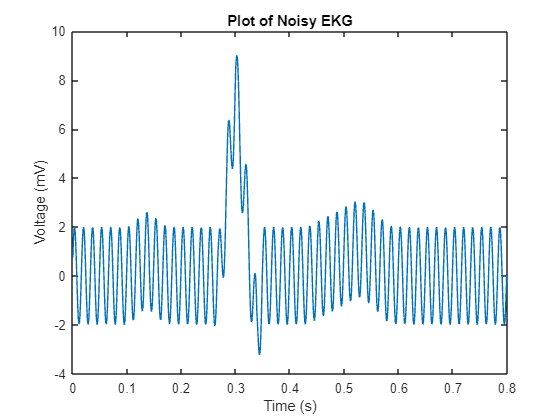


plot (t, ekg60n);
    title ("Plot of Noisy EKG");
    xlabel("Time (s)");
    ylabel("Voltage (mV)");

## 3B. Plot the magnitude of the Fourier transforms of ekg and ekg60n as a function of frequency (in Hz) in 0 to 100 Hz range, i.e. plto only the partial results. This will better display the signals of interest. Use a 1024 point FFT. Note that the matlab will automatically append zeros to your data points (to make it 1024 points long) if you gave the command fft(ekg, 1024). Label various signals present in the power spectral density.

Note that most of the ekg data is confined to <25Hz. In the ekg60n spectrum, in addition to low frequency component (<25Hz) representing the patient's heartbeat, there is a sharp peak at 60HZ (power-line) and a low amplitude wideband component (due to random noise).

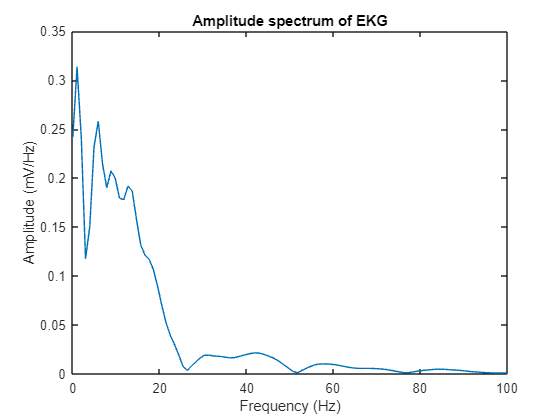

%generating the frequency axis
N = 2^10 ; %1024 points for the FFT
df = fs/N;
f = -(fs/2 - df): df: fs/2;

%now, transforming the ekg, ekg60n curves to their fourier domain form
EKG = ts *fftshift (fft(ekg, N));
EKG60N = ts*fftshift(fft(ekg60n, N));

%and at last, plotting the frequency form
%note from 0 to 100Hz in range....

plot (f, abs (EKG));
    title ("Amplitude spectrum of EKG");
    xlabel("Frequency (Hz)");
    ylabel("Amplitude (mV/Hz)");
    xlim([0, 100]);

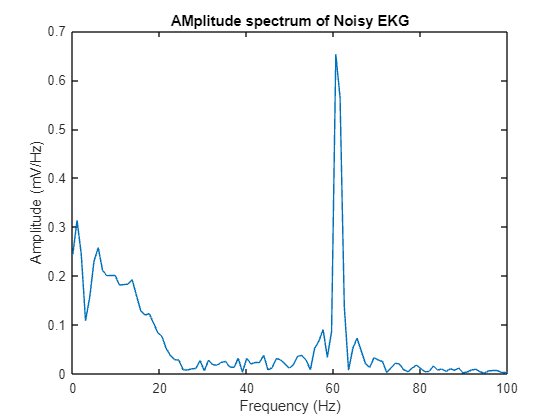


plot (f, abs(EKG60N));
    title ("AMplitude spectrum of Noisy EKG");
    xlabel("Frequency (Hz)");
    ylabel("Amplitude (mV/Hz)");
    xlim ([0, 100]);

## 3C.1. Our objective is to filter the data to remove the large peak at 60 Hz and to minimize the random noise. We  are going to use the low pass RC filter of Examples 3.1-1 and 3.1-2 of Carlson; the first example gives the  impulse response (equation 8b) and the second the frequency response (equations 18a, b). Note that a single  parameter - the product RC or B (B = 1/2πRC ) - determines the filter properties, in this case the frequency of  the 3 dB point. We shall design two filters with the following bandwidths:

##   (i) B = 30 Hz

##  (ii) B = 50 Hz 

## Write down the expressions for the impulse responses h30(t) and h50(t) for the filters. Discretize each filter to  obtain digital filters represented by h30(n) and h50(n). Choose sampling frequency to be fs = 1000 Hz (sampling  period Ts = 0.001, i.e. discretize using t = 0.001 ∗ n, n = 0, 1, 2, 3, ...... Choose the length N of the discretized  filters such that (N − 1)Ts = 4RC, i.e. truncate the analog impulse response at four time constants (4RC). Note  that the lengths of the two filters will be different.

%okay so first, defining bandwidths and related time axes for the LPFs is
%required

%B= 30hz
B3 = 30;
t3 = 0:ts : 2/(pi*B3);

%impulse response...
h3 = (2*pi*B3)*exp(-(2*pi*B3)*t3); %notice impulse has the exponent!

%B = 50 Hz
B5 = 50;
t5 = 0:ts : 2/(pi*B5);

h5 = (2*pi*B5)*exp(-(2*pi*B5)*t5); %and for B = 50hz as well...


##  3C.2.Plot the impulse response (discretized version) for each filter as a function of time (seconds). 

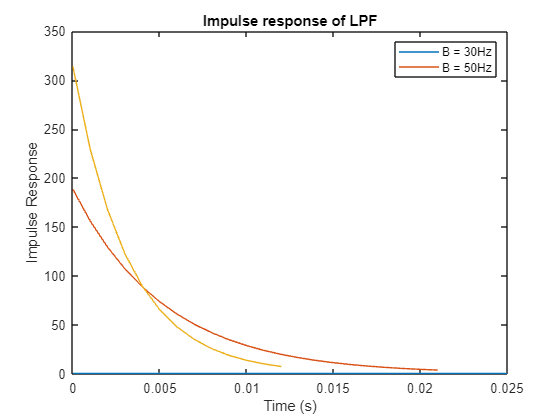

%now, using the code from 3.c.1...

hold on % this will let us plot both on the same graph!

plot (t3, h3);
plot (t5, h5);

hold off; 
    title ("Impulse response of LPF");
    xlabel("Time (s)");
    ylabel("Impulse Response");
    legend ('B = 30Hz', 'B = 50Hz'); %this should correlate directly with the first and second plot respectively when plotted.

    xlim([0, 0.025]); %this should display better...

## 3.C.3. Use a 1024 point FFT to determine the frequency response of each filter. Plot the amplitude |H(f)| and phase  for each filter as a function of frequency in the range 0 to 100 Hz. What is the magnitude (in dB) of |H(f =  60Hz)|/|H(f = 0Hz)| for each filter?

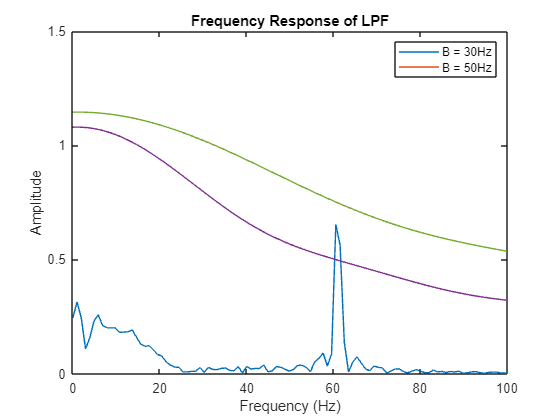

%generating the frequency axis
N = 2^10 ; %1024 points for the FFT
df = fs/N;
f = -(fs/2 - df): df: fs/2;

    %now, transforming the LPFs to frequency domain
    H3 = ts*fftshift (fft(h3, N));
    H5 = ts*fftshift(fft(h5, N));

    %and lastly, plotting these two on the same graph

    hold on;
    plot (f, abs(H3));
    plot (f, abs(H5));
    hold off;
        xlim ([0, 100]);
        ylim([0, 1.5]);
        title ("Frequency Response of LPF");
        xlabel("Frequency (Hz)");
        ylabel("Amplitude");
        legend ('B = 30Hz', 'B = 50Hz'); %the colors are no longer correlating correctly...

 B = 30Hz, |H(f = 60Hz)|/|H(f = 0Hz)| =~ -6.65 dB. 

B = 50Hz, |H(f = 60Hz)|/|H(f = 0Hz)| =~ -3.7 dB. 

## 3D.1. Multiply the Fourier transform of ekg60n found in 3A. to those of the filters found in 3C.2. to obtain 1024 point  output Fourier transform Y (f) for each of the filters (Note: Y (f) = H(f)X(f)). Plot Y (f) in each case as a function of  frequency (Hz) in 0 to 100 Hz range. 

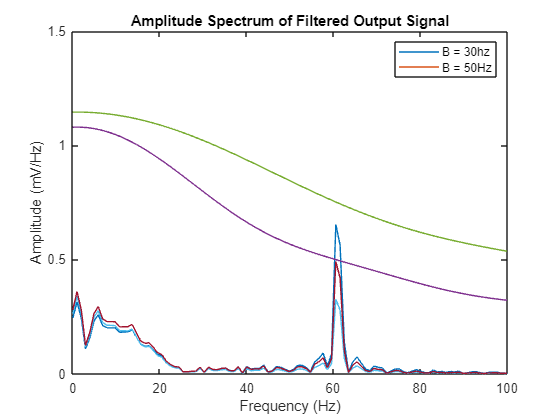

%frequency data again
N = 2^10 ; %1024 points for the FFT
df = fs/N;
f = -(fs/2 - df): df: fs/2;

%defining the spectrum.... Y(f)
Y3 = EKG60N.*H3;
Y5 = EKG60N.*H5;

%and finally plotting the Y(f)
hold on;
plot (f, abs(Y3));
plot (f, abs (Y5));
hold off;
    xlim ([0, 100]);
    ylim([0,1.5]);
    title ("Amplitude Spectrum of Filtered Output Signal");
    xlabel("Frequency (Hz)");
    ylabel("Amplitude (mV/Hz)");
    legend ('B = 30hz', 'B = 50Hz');

## 3D.2. Use a 1024 point inverse FFT (IFFT) to find y(t) in each case. Plot y(t) in each case as a function of time (s).  Compare filtered ekg60n, i.e. y(t) in each case with ekg. Which of the two filters works better? Why?

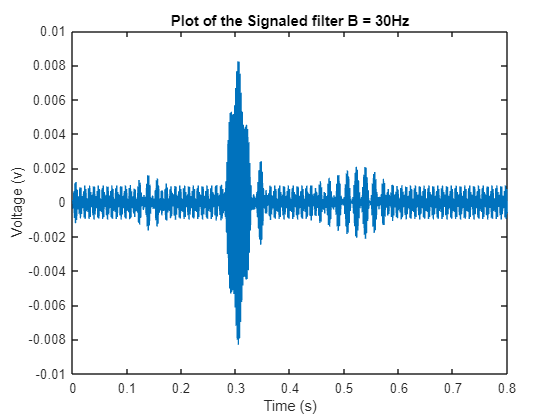

 %generated values from 3d.2
 dt = N/fs;
 t = 0:ts : dt-ts;

 %now defining the filtering outputs....
 y3 = ifft(Y3); %notice the ifft...
 y5 = ifft(Y5);

 %and lastly, plotting the filtered output.
 plot (t, y3);
    title("Plot of the Signaled filter B = 30Hz");
    xlabel("Time (s)");
    ylabel("Voltage (v)");
    xlim ([0, 0.8]);

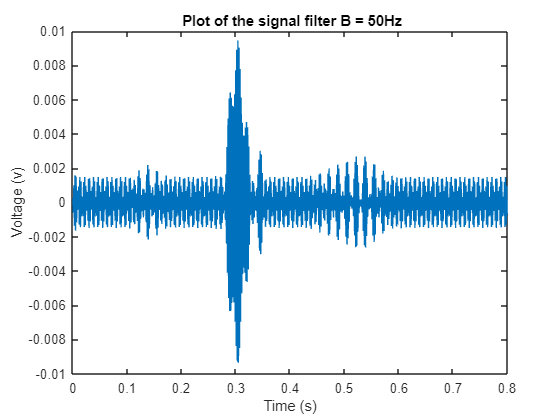


 
 plot (t, y5);
    title(" Plot of the signal filter B = 50Hz");
    xlabel("Time (s)");
    ylabel("Voltage (v)");
    xlim([0 ,0.8]);

Comparison Results:

 As can be seen by comparing all the figures and plots that are shown above, we can gather that there is a noticeable difference in amplitude from ekg in comparison to the noisy ekg (ekg60n), in addition to there being a more easily viewed waveform when looking at these two plots when using the 30Hz filter. This filter not only elimiinates more of the noise, or the amount of amplitude difference between the original value, and what we are looking to acomplish, in comparison to the result when filtered through B = 50Hz. 